clear
rosshutdown

Shutting down global node /matlab_global_node_41899 with NodeURI http://192.168.1.100:61467/


setenv('ROS_MASTER_URI','http://192.168.1.200:11311')
setenv('ROS_IP','192.168.1.100')
rosinit('http://192.168.1.200:11311');

The value of the ROS_IP environment variable, 192.168.1.100, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_90283 with NodeURI http://192.168.1.100:61512/


path = [0 0; 0 0.5; 0 1; 0 1.5; 0 2; 0.5 2; 1 2; 1.5 2; 2 2;2 1.5; 2 1; 2 0.5; 2 0; 2 0;1.5 0;1 0;0.5 0];
robotInitialLocation = path(1,:);
robotGoal = path(end,:);
initialOrientation = 0;
robotCurrentPose = [robotInitialLocation, initialOrientation]';

robot = differentialDriveKinematics("TrackWidth", 0.5, "VehicleInputs", "VehicleSpeedHeadingRate");

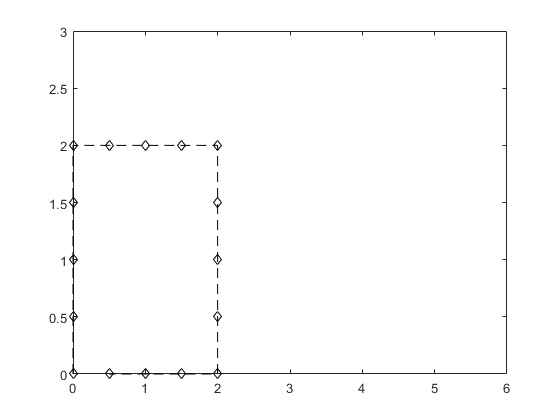

figure
plot(path(:,1), path(:,2),'k--d')
xlim([0 6])
ylim([0 3])

controller = controllerPurePursuit;

controller.Waypoints = path;

controller.DesiredLinearVelocity = 0.5;

controller.MaxAngularVelocity = 2;

controller.LookaheadDistance = 0.3;

goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);

% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/0.8;

robotRealLife = rospublisher('/mobile_base/commands/velocity');
odom = rossubscriber('/odom');

resetPos = rospublisher('/mobile_base/commands/reset_odometry');
velmsg = rosmessage(robotRealLife);
resetmsg = rosmessage(resetPos);
send(resetPos, resetmsg);

while( distanceToGoal > goalRadius )
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
 
    velmsg.Angular.Z = omega;
    velmsg.Linear.X = v;
    %velmsg.Angular.Y = vel(2);
    send(robotRealLife,velmsg);
   
    odomdata = receive(odom);
    pose = odomdata.Pose.Pose;
    x = pose.Position.X;
    y = pose.Position.Y;
    z = pose.Position.Z;
    
    %robotCurrentPose = [x, y, z];
    
    disp(robotCurrentPose)
    % Update the current pose
    robotCurrentPose = robotCurrentPose +vel*sampleTime
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
   
   %controller.release();
    waitfor(vizRate);
end

     0
     0
     0



robotCurrentPose =     0.0500
         0
    0.2000


    0.0500
         0
    0.2000



robotCurrentPose =     0.0990
    0.0099
    0.4000


    0.0990
    0.0099
    0.4000



robotCurrentPose =     0.1451
    0.0294
    0.6000


    0.1451
    0.0294
    0.6000



robotCurrentPose =     0.1863
    0.0576
    0.8000


    0.1863
    0.0576
    0.8000



robotCurrentPose =     0.2212
    0.0935
    1.0000


    0.2212
    0.0935
    1.0000



robotCurrentPose =     0.2482
    0.1356
    1.2000


    0.2482
    0.1356
    1.2000



robotCurrentPose =     0.2663
    0.1822
    1.4000


    0.2663
    0.1822
    1.4000



robotCurrentPose =     0.2748
    0.2315
    1.6000


    0.2748
    0.2315
    1.6000



robotCurrentPose =     0.2733
    0.2814
    1.8000


    0.2733
    0.2814
    1.8000



robotCurrentPose =     0.2620
    0.3301
    2.0000


    0.2620
    0.3301
    2.0000



robotCurrentPose =     0.2412
    0.3756
    2.1898


    0.2412
    0.3756
    2.1898



robotCurrentPose =     0.2122
    0.4163
    2.2285


    0.2122
    0.4163
    2.2285



robotCurrentPose =     0.1816
    0.4559
    2.2004


    0.1816
    0.4559
    2.2004



robotCurrentPose =     0.1521
    0.4963
    2.1436


    0.1521
    0.4963
    2.1436



robotCurrentPose =     0.1250
    0.5383
    2.0748


    0.1250
    0.5383
    2.0748



robotCurrentPose =     0.1009
    0.5821
    2.0022


    0.1009
    0.5821
    2.0022



robotCurrentPose =     0.0800
    0.6275
    1.9310


    0.0800
    0.6275
    1.9310



robotCurrentPose =     0.0624
    0.6743
    1.8647


    0.0624
    0.6743
    1.8647



robotCurrentPose =     0.0479
    0.7222
    1.8055


    0.0479
    0.7222
    1.8055



robotCurrentPose =     0.0363
    0.7708
    1.7546


    0.0363
    0.7708
    1.7546



robotCurrentPose =     0.0271
    0.8200
    1.7123


    0.0271
    0.8200
    1.7123



robotCurrentPose =     0.0201
    0.8695
    1.6781


    0.0201
    0.8695
    1.6781



robotCurrentPose =     0.0147
    0.9192
    1.6511


    0.0147
    0.9192
    1.6511



robotCurrentPose =     0.0107
    0.9690
    1.6302


    0.0107
    0.9690
    1.6302



robotCurrentPose =     0.0077
    1.0189
    1.6144


    0.0077
    1.0189
    1.6144



robotCurrentPose =     0.0056
    1.0689
    1.6025


    0.0056
    1.0689
    1.6025



robotCurrentPose =     0.0040
    1.1188
    1.5937


    0.0040
    1.1188
    1.5937



robotCurrentPose =     0.0028
    1.1688
    1.5873


    0.0028
    1.1688
    1.5873



robotCurrentPose =     0.0020
    1.2188
    1.5826


    0.0020
    1.2188
    1.5826



robotCurrentPose =     0.0014
    1.2688
    1.5792


    0.0014
    1.2688
    1.5792



robotCurrentPose =     0.0010
    1.3188
    1.5767


    0.0010
    1.3188
    1.5767



robotCurrentPose =     0.0007
    1.3688
    1.5750


    0.0007
    1.3688
    1.5750



robotCurrentPose =     0.0005
    1.4188
    1.5737


    0.0005
    1.4188
    1.5737



robotCurrentPose =     0.0003
    1.4688
    1.5729


    0.0003
    1.4688
    1.5729



robotCurrentPose =     0.0002
    1.5188
    1.5722


    0.0002
    1.5188
    1.5722



robotCurrentPose =     0.0002
    1.5688
    1.5718


    0.0002
    1.5688
    1.5718



robotCurrentPose =     0.0001
    1.6188
    1.5715


    0.0001
    1.6188
    1.5715



robotCurrentPose =     0.0001
    1.6688
    1.5713


    0.0001
    1.6688
    1.5713



robotCurrentPose =     0.0001
    1.7188
    1.5711


    0.0001
    1.7188
    1.5711



robotCurrentPose =     0.0000
    1.7688
    1.5265


    0.0000
    1.7688
    1.5265



robotCurrentPose =     0.0023
    1.8188
    1.3649


    0.0023
    1.8188
    1.3649



robotCurrentPose =     0.0125
    1.8677
    1.1649


    0.0125
    1.8677
    1.1649



robotCurrentPose =     0.0322
    1.9136
    0.9649


    0.0322
    1.9136
    0.9649



robotCurrentPose =     0.0607
    1.9547
    0.7649


    0.0607
    1.9547
    0.7649



robotCurrentPose =     0.0968
    1.9894
    0.5649


    0.0968
    1.9894
    0.5649



robotCurrentPose =     0.1390
    2.0161
    0.3649


    0.1390
    2.0161
    0.3649



robotCurrentPose =     0.1857
    2.0340
    0.1649


    0.1857
    2.0340
    0.1649



robotCurrentPose =     0.2350
    2.0422
   -0.0179


    0.2350
    2.0422
   -0.0179



robotCurrentPose =     0.2850
    2.0413
   -0.0989


    0.2850
    2.0413
   -0.0989



robotCurrentPose =     0.3348
    2.0364
   -0.1241


    0.3348
    2.0364
   -0.1241



robotCurrentPose =     0.3844
    2.0302
   -0.1218


    0.3844
    2.0302
   -0.1218



robotCurrentPose =     0.4340
    2.0241
   -0.1074


    0.4340
    2.0241
   -0.1074



robotCurrentPose =     0.4837
    2.0187
   -0.0892


    0.4837
    2.0187
   -0.0892



robotCurrentPose =     0.5335
    2.0143
   -0.0713


    0.5335
    2.0143
   -0.0713



robotCurrentPose =     0.5834
    2.0107
   -0.0555


    0.5834
    2.0107
   -0.0555



robotCurrentPose =     0.6333
    2.0079
   -0.0423


    0.6333
    2.0079
   -0.0423



robotCurrentPose =     0.6833
    2.0058
   -0.0317


    0.6833
    2.0058
   -0.0317



robotCurrentPose =     0.7333
    2.0042
   -0.0235


    0.7333
    2.0042
   -0.0235



robotCurrentPose =     0.7832
    2.0031
   -0.0173


    0.7832
    2.0031
   -0.0173



robotCurrentPose =     0.8332
    2.0022
   -0.0126


    0.8332
    2.0022
   -0.0126



robotCurrentPose =     0.8832
    2.0016
   -0.0091


    0.8832
    2.0016
   -0.0091



robotCurrentPose =     0.9332
    2.0011
   -0.0065


    0.9332
    2.0011
   -0.0065



robotCurrentPose =     0.9832
    2.0008
   -0.0047


    0.9832
    2.0008
   -0.0047



robotCurrentPose =     1.0332
    2.0006
   -0.0033


    1.0332
    2.0006
   -0.0033



robotCurrentPose =     1.0832
    2.0004
   -0.0023


    1.0832
    2.0004
   -0.0023



robotCurrentPose =     1.1332
    2.0003
   -0.0017


    1.1332
    2.0003
   -0.0017



robotCurrentPose =     1.1832
    2.0002
   -0.0012


    1.1832
    2.0002
   -0.0012



robotCurrentPose =     1.2332
    2.0001
   -0.0008


    1.2332
    2.0001
   -0.0008



robotCurrentPose =     1.2832
    2.0001
   -0.0006


    1.2832
    2.0001
   -0.0006



robotCurrentPose =     1.3332
    2.0001
   -0.0004


    1.3332
    2.0001
   -0.0004



robotCurrentPose =     1.3832
    2.0000
   -0.0003


    1.3832
    2.0000
   -0.0003



robotCurrentPose =     1.4332
    2.0000
   -0.0002


    1.4332
    2.0000
   -0.0002



robotCurrentPose =     1.4832
    2.0000
   -0.0001


    1.4832
    2.0000
   -0.0001



robotCurrentPose =     1.5332
    2.0000
   -0.0001


    1.5332
    2.0000
   -0.0001



robotCurrentPose =     1.5832
    2.0000
   -0.0001


    1.5832
    2.0000
   -0.0001



robotCurrentPose =     1.6332
    2.0000
   -0.0000


    1.6332
    2.0000
   -0.0000



robotCurrentPose =     1.6832
    2.0000
   -0.0000


    1.6832
    2.0000
   -0.0000



robotCurrentPose =     1.7332
    2.0000
   -0.0000


    1.7332
    2.0000
   -0.0000



robotCurrentPose =     1.7832
    2.0000
   -0.0824


    1.7832
    2.0000
   -0.0824



robotCurrentPose =     1.8331
    1.9959
   -0.2693


    1.8331
    1.9959
   -0.2693



robotCurrentPose =     1.8813
    1.9826
   -0.4693


    1.8813
    1.9826
   -0.4693



robotCurrentPose =     1.9258
    1.9600
   -0.6693


    1.9258
    1.9600
   -0.6693



robotCurrentPose =     1.9651
    1.9289
   -0.8693


    1.9651
    1.9289
   -0.8693



robotCurrentPose =     1.9973
    1.8907
   -1.0693


    1.9973
    1.8907
   -1.0693



robotCurrentPose =     2.0214
    1.8469
   -1.2693


    2.0214
    1.8469
   -1.2693



robotCurrentPose =     2.0362
    1.7992
   -1.4693


    2.0362
    1.7992
   -1.4693



robotCurrentPose =     2.0413
    1.7494
   -1.6158


    2.0413
    1.7494
   -1.6158



robotCurrentPose =     2.0390
    1.6995
   -1.6769


    2.0390
    1.6995
   -1.6769



robotCurrentPose =     2.0337
    1.6497
   -1.6924


    2.0337
    1.6497
   -1.6924



robotCurrentPose =     2.0277
    1.6001
   -1.6860


    2.0277
    1.6001
   -1.6860



robotCurrentPose =     2.0219
    1.5505
   -1.6705


    2.0219
    1.5505
   -1.6705



robotCurrentPose =     2.0169
    1.5007
   -1.6527


    2.0169
    1.5007
   -1.6527



robotCurrentPose =     2.0129
    1.4509
   -1.6357


    2.0129
    1.4509
   -1.6357



robotCurrentPose =     2.0096
    1.4010
   -1.6210


    2.0096
    1.4010
   -1.6210



robotCurrentPose =     2.0071
    1.3510
   -1.6089


    2.0071
    1.3510
   -1.6089



robotCurrentPose =     2.0052
    1.3011
   -1.5993


    2.0052
    1.3011
   -1.5993



robotCurrentPose =     2.0038
    1.2511
   -1.5918


    2.0038
    1.2511
   -1.5918



robotCurrentPose =     2.0027
    1.2011
   -1.5862


    2.0027
    1.2011
   -1.5862



robotCurrentPose =     2.0020
    1.1511
   -1.5820


    2.0020
    1.1511
   -1.5820



robotCurrentPose =     2.0014
    1.1011
   -1.5789


    2.0014
    1.1011
   -1.5789



robotCurrentPose =     2.0010
    1.0511
   -1.5766


    2.0010
    1.0511
   -1.5766



robotCurrentPose =     2.0007
    1.0011
   -1.5749


    2.0007
    1.0011
   -1.5749



robotCurrentPose =     2.0005
    0.9511
   -1.5737


    2.0005
    0.9511
   -1.5737



robotCurrentPose =     2.0003
    0.9011
   -1.5729


    2.0003
    0.9011
   -1.5729



robotCurrentPose =     2.0002
    0.8511
   -1.5723


    2.0002
    0.8511
   -1.5723



robotCurrentPose =     2.0002
    0.8011
   -1.5718


    2.0002
    0.8011
   -1.5718



robotCurrentPose =     2.0001
    0.7511
   -1.5715


    2.0001
    0.7511
   -1.5715



robotCurrentPose =     2.0001
    0.7011
   -1.5713


    2.0001
    0.7011
   -1.5713



robotCurrentPose =     2.0001
    0.6511
   -1.5711


    2.0001
    0.6511
   -1.5711



robotCurrentPose =     2.0000
    0.6011
   -1.5710


    2.0000
    0.6011
   -1.5710



robotCurrentPose =     2.0000
    0.5511
   -1.5710


    2.0000
    0.5511
   -1.5710



robotCurrentPose =     2.0000
    0.5011
   -1.5709


    2.0000
    0.5011
   -1.5709



robotCurrentPose =     2.0000
    0.4511
   -1.5709


    2.0000
    0.4511
   -1.5709



robotCurrentPose =     2.0000
    0.4011
   -1.5709


    2.0000
    0.4011
   -1.5709



robotCurrentPose =     2.0000
    0.3511
   -1.5708


    2.0000
    0.3511
   -1.5708



robotCurrentPose =     2.0000
    0.3011
   -1.5708


    2.0000
    0.3011
   -1.5708



robotCurrentPose =     2.0000
    0.2511
   -1.5708


    2.0000
    0.2511
   -1.5708



robotCurrentPose =     2.0000
    0.2011
   -1.6982


    2.0000
    0.2011
   -1.6982



robotCurrentPose =     1.9936
    0.1515
   -1.8982


    1.9936
    0.1515
   -1.8982



robotCurrentPose =     1.9776
    0.1042
   -2.0982


    1.9776
    0.1042
   -2.0982



robotCurrentPose =     1.9524
    0.0610
   -2.2982


    1.9524
    0.0610
   -2.2982



robotCurrentPose =     1.9192
    0.0236
   -2.4982


    1.9192
    0.0236
   -2.4982



robotCurrentPose =     1.8792
   -0.0064
   -2.6982


    1.8792
   -0.0064
   -2.6982



robotCurrentPose =     1.8340
   -0.0278
   -2.8982


    1.8340
   -0.0278
   -2.8982



robotCurrentPose =     1.7855
   -0.0399
   -3.0982


    1.7855
   -0.0399
   -3.0982



robotCurrentPose =     1.7355
   -0.0420
   -3.2146


    1.7355
   -0.0420
   -3.2146



robotCurrentPose =     1.6856
   -0.0384
   -3.2587


    1.6856
   -0.0384
   -3.2587



robotCurrentPose =     1.6360
   -0.0325
   -3.2655


    1.6360
   -0.0325
   -3.2655



robotCurrentPose =     1.5864
   -0.0264
   -3.2549


    1.5864
   -0.0264
   -3.2549



robotCurrentPose =     1.5367
   -0.0207
   -3.2378


    1.5367
   -0.0207
   -3.2378



robotCurrentPose =     1.4869
   -0.0159
   -3.2196


    1.4869
   -0.0159
   -3.2196



robotCurrentPose =     1.4371
   -0.0120
   -3.2029


    1.4371
   -0.0120
   -3.2029



robotCurrentPose =     1.3872
   -0.0089
   -3.1887


    1.3872
   -0.0089
   -3.1887



robotCurrentPose =     1.3372
   -0.0066
   -3.1772


    1.3372
   -0.0066
   -3.1772



robotCurrentPose =     1.2873
   -0.0048
   -3.1681


    1.2873
   -0.0048
   -3.1681



robotCurrentPose =     1.2373
   -0.0035
   -3.1611


    1.2373
   -0.0035
   -3.1611



robotCurrentPose =     1.1873
   -0.0025
   -3.1559


    1.1873
   -0.0025
   -3.1559



robotCurrentPose =     1.1373
   -0.0018
   -3.1519


    1.1373
   -0.0018
   -3.1519



robotCurrentPose =     1.0873
   -0.0013
   -3.1490


    1.0873
   -0.0013
   -3.1490



robotCurrentPose =     1.0373
   -0.0009
   -3.1469


    1.0373
   -0.0009
   -3.1469



robotCurrentPose =     0.9873
   -0.0006
   -3.1454


    0.9873
   -0.0006
   -3.1454



robotCurrentPose =     0.9373
   -0.0005
   -3.1443


    0.9373
   -0.0005
   -3.1443



robotCurrentPose =     0.8873
   -0.0003
   -3.1435


    0.8873
   -0.0003
   -3.1435



robotCurrentPose =     0.8373
   -0.0002
   -3.1429


    0.8373
   -0.0002
   -3.1429



robotCurrentPose =     0.7873
   -0.0002
   -3.1425


    0.7873
   -0.0002
   -3.1425



robotCurrentPose =     0.7373
   -0.0001
   -3.1423


    0.7373
   -0.0001
   -3.1423



robotCurrentPose =     0.6873
   -0.0001
   -3.1421


    0.6873
   -0.0001
   -3.1421



robotCurrentPose =     0.6373
   -0.0000
   -3.1420


    0.6373
   -0.0000
   -3.1420



robotCurrentPose =     0.5873
   -0.0000
   -3.1420



velocity = 0;
velmsg.Linear.X = velocity;
send(robotRealLife, velmsg)